# Laboratorio 3 Robótica: Modelo diferencial de primer orden

## Universidad Nacional de Colombia

## Alejandro Ojeda Olarte, Brayan Calderon, Mateo Rodriguez

## Asignacion de Ruta

Teniendo en cuenta el robot asignado y los resultados obtenidos en el Lab 1  Análisis de las características de un Robot Industrial y Modelo geométrico directo. Resuelva los siguientes enunciados.

#### 1.Se asigna un plano en el que debe crear una ruta y simular el movimiento de seguimiento del robot. Deberá presentarla simulación de al menos una de las rutas propuestas, pueden crear y simular otras rutas y/o otros planos.

Para el grupo 1, nos toca el vector $\left\lbrack \begin{array}{ccc}
1 & 0 & 1
\end{array}\right\rbrack$. Se escoge la segunda figura de las opciones, y dado que el alcance del robot es 500mm, la dimensión L será 200mm. Se define una longitud del tramo largo recto de 150mm, un ancho de 150mm y un radio para el semicírculo de 50mm. La trayectoria se grafica a continuación.

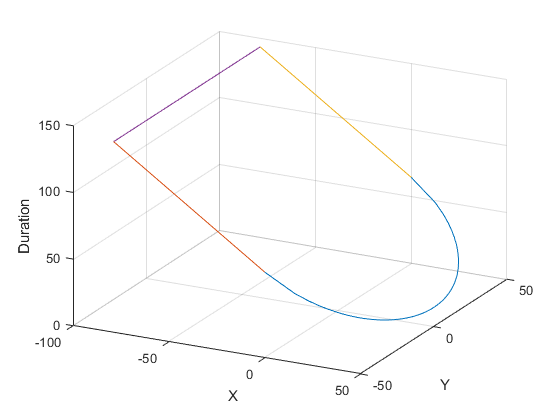

resolution=50;
radius=50; %In mm
L_side=150; %in mm

curve_y=linspace(-50,50,resolution);
curve_x=sqrt(-curve_y.^2 + radius^2);
curve_z=-curve_x+(L_side*cos(45)*0.5)+(radius*0.5);

side_x=linspace(-(L_side*cos(45)),0,resolution);
side_1y=ones(1,length(side_x))*-radius;
side_2y=ones(1,length(side_x))*+radius;
sides_z=-side_x+(L_side*cos(45)*0.5)+(radius*0.5);

cross_x=ones(1,length(side_x))*min(side_x);
cross_y=linspace(-radius,radius,resolution);
cross_z=ones(1,length(side_x))*max(sides_z);


plot3(curve_x,curve_y,curve_z)
hold on
plot3(side_x,side_1y,sides_z)
plot3(side_x,side_2y,sides_z)
plot3(cross_x,cross_y,cross_z)
xlabel('X')
ylabel('Y')
zlabel('Duration')
grid on

view([27 28])

#### 2.En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de 